# **WM9QE: Applied Statistics for Artificial Intelligence**

## **Simple Linear Regression (SLR)**

This MATLAB Live Script is a suppliment to the Simple Linear Regression session. Full detail of the lectures and examples are availabe on [Section: Week Three | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=621569)

Learning Objectives

- Build and interpret linear regression models from scratch

- Evaluate model quality using multiple complementary metrics

- Diagnose assumption violations through residual analysis

Overview

This foundational session introduces Simple Linear Regression (SLR), one of the most interpretable and widely-used predictive models in machine learning and AI systems. While modern AI often employs complex deep learning architectures, SLR remains invaluable for understanding relationships between variables, establishing baselines, and solving problems where interpretability is paramount.

The session bridges statistical theory with practical AI applications, demonstrating how SLR serves as both a standalone tool and a conceptual foundation for more advanced techniques. You will learn not only how to build regression models but, critically, how to validate their assumptions, diagnose problems, and deploy them reliably in production environments.

# 1 Training and Validating the Model

% Independent Variable (Adverstisement Spending)
X = [1784.58;2576.63;3148.32;2224.88;2676.73;1814.69;2425.06;2475.72;2378.58;2755.48;2563.37;2158;2117.26;1985.55;3005.69;3014.65;2856.69;1958;1896.59;2646.43;2876.58;2250.69;2895.68;2370.9];

%Dependent variable (revenue)
Y = [5995.48;11087.7;12850.94;8072.03;9871.44;7137.16;10457.57;8330.34;9243.69;11542.7;9725.25;7256;8805.13;7526.36;12546.28;13589.67;10989.62;6139.1;6759.36;11809.99;12586.34;9986.58;12036.67;8482.15];

% --- Fit linear model using fitlm ---
mdl = fitlm(X, Y);

% Extract stats
a = mdl.Coefficients.Estimate(1);   % intercept
b = mdl.Coefficients.Estimate(2);   % slope
Y_pred = predict(mdl, X);           % fitted values at each X

% Check how good the model is.
R2      = mdl.Rsquared.Ordinary;
RMSE    = mdl.RMSE;


% --- Residuals ---
residuals_tbl = table(mdl.Fitted, mdl.Residuals.Raw, zscore(mdl.Residuals.Raw), mdl.Residuals.Standardized, ...
                      'VariableNames', {'Fitted Vals', 'Residuals', 'zscore residuals', 'Standardised'});

% Alternative way to calculate mdl.Residuals.Raw Residuals
%residuals = Y - Y_pred;

**Visualisations**

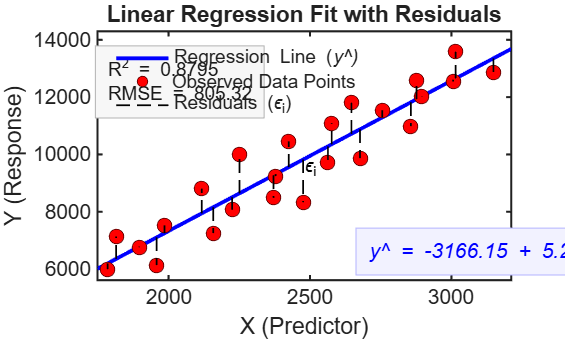

%Extracting values from the model (mdl)
raw_resid          = mdl.Residuals.Raw;          % observed - fitted
standardised_res   = zscore(mdl.Residuals.Raw);  % zscore standardised residuals
fitted_vals        = mdl.Fitted;                 % same as Y_pred
obs_index          = (1:numel(X))';              % "Order" (observation number)

% --- Generate smooth line for plotting the regression line ---
X_line = linspace(min(X)*0.98, max(X)*1.02, 200)';    
Y_line = predict(mdl, X_line);

%% --- Plot ---
figure('Color','w','Position',[200 200 900 540]);
hold on;

% 1. Regression line (ŷ)
plot(X_line, Y_line, 'b-', 'LineWidth', 2.2);

% 2. Observed data points
scatter(X, Y, 70, 'r', 'filled', 'MarkerEdgeColor', [0.4 0 0]);

% 3. Residual "sticks" for each point
for i = 1:length(X)
    plot([X(i) X(i)], [Y_pred(i) Y(i)], 'k--', 'LineWidth', 1);
end

% 4. Label one of the residuals εᵢ for teaching
[~, worstIdx] = max(abs(mdl.Residuals.Raw));
text(X(worstIdx), (Y(worstIdx)+Y_pred(worstIdx))/2, '\epsilon_i', ...
     'FontSize',11,'Color','k','HorizontalAlignment','left','VerticalAlignment','bottom');

% --- Compute coordinate bounds for flexible annotation placement ---
x_min = min(X_line);
x_max = max(X_line);
y_min = min([Y; Y_line]);
y_max = max([Y; Y_line]);

% 5. Annotate regression line
eqnStr = sprintf('\\ity\\^ = %.2f + %.2f x', a, b);
text(x_max - 0.35*(x_max - x_min), ...
     y_min + 0.08*(y_max - y_min), ...
     eqnStr, ...
     'Color','b','FontSize',12,'FontAngle','italic', ...
     'BackgroundColor',[0.95 0.95 1], 'EdgeColor',[0.7 0.7 1], ...
     'Margin',6,'Clipping','on');

% 6. Stats box (R² and RMSE) in top-left corner
statsStr = sprintf('R^2 = %.4f\nRMSE = %.2f', R2, RMSE);
text(x_min + 0.02*(x_max - x_min), ...
     y_max - 0.15*(y_max - y_min), ...
     statsStr, ...
     'Color',[0.1 0.1 0.1],'FontSize',11, ...
     'BackgroundColor',[0.97 0.97 0.97], 'EdgeColor',[0.7 0.7 0.7], ...
     'Margin',6,'Clipping','on');

% Axes labels & appearance
xlabel('X (Predictor)','FontSize',12);
ylabel('Y (Response)','FontSize',12);
set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');

xlim([x_min x_max]);
ylim([y_min - 0.05*(y_max - y_min), y_max + 0.08*(y_max - y_min)]);

% Legend
legend({'Regression Line (\ity\^)', 'Observed Data Points', 'Residuals (\epsilon_i)'}, ...
       'Location','northwest','Box','off','Interpreter','tex');

title('Linear Regression Fit with Residuals','FontSize',13);
hold off;

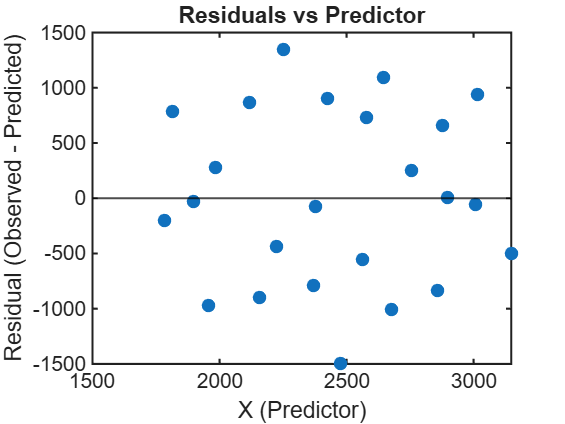


%% --- 1. Residual diagnostics plot ---
figure('Color','w','Position',[250 250 560 420]);
scatter(X, raw_resid, 60, 'filled');
yline(0,'k-','LineWidth',1.2);
xlabel('X (Predictor)','FontSize',12);
ylabel('Residual (Observed - Predicted)','FontSize',12);
title('Residuals vs Predictor','FontSize',13);
set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');

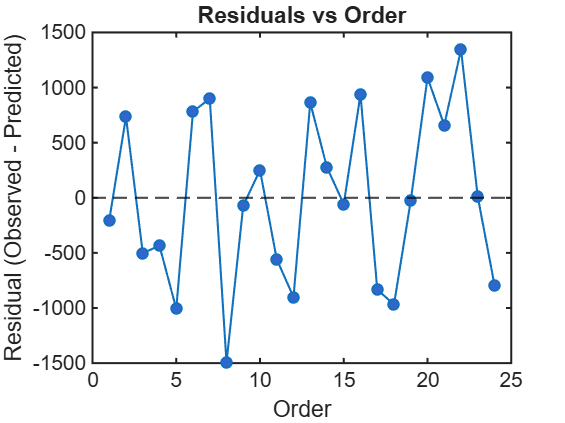


%% --- 2. Residuals vs Order (Independence check)
figure('Color','w','Position',[260 260 560 420]);
plot(obs_index, raw_resid, '-o', 'LineWidth',1.2, 'MarkerFaceColor',[0.2 0.4 0.8]);
yline(0,'k--','LineWidth',1.2);
xlabel('Order','FontSize',12);
ylabel('Residual (Observed - Predicted)','FontSize',12);
title('Residuals vs Order','FontSize',13);
set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');

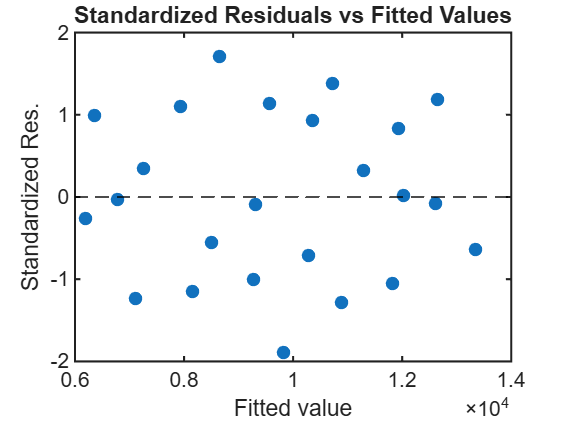


% Interpretation:
% - We want randomness around 0, not clear upward/downward trends or cycles.
% - Obvious structure would suggest non-independence / time effects / drift.

%% --- 3. Standardised Residuals vs Fitted Values
figure('Color','w','Position',[280 280 560 420]);
scatter(fitted_vals, standardised_res, 60, 'filled');
yline(0,'k--','LineWidth',1.2);
xlabel('Fitted value','FontSize',12);
ylabel('Standardized Res.','FontSize',12);
title('Standardized Residuals vs Fitted Values','FontSize',13);
set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');

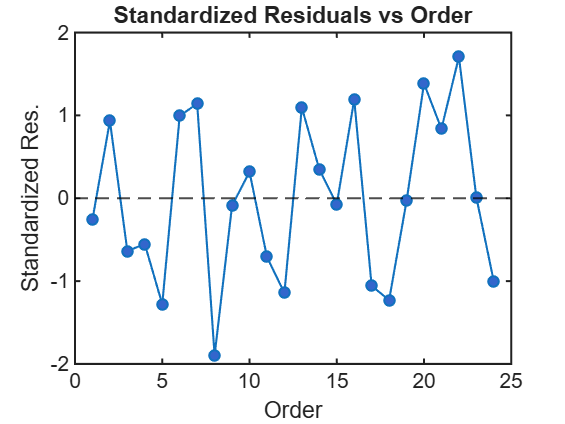


%% --- 4. Standardised Residuals vs Order
figure('Color','w','Position',[270 270 560 420]);
plot(obs_index, standardised_res, '-o', 'LineWidth',1.2, 'MarkerFaceColor',[0.2 0.4 0.8]);
yline(0,'k--','LineWidth',1.2);
xlabel('Order','FontSize',12);
ylabel('Standardized Res.','FontSize',12);
title('Standardized Residuals vs Order','FontSize',13);
set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');



% Interpretation:
% • We want no "funnel" shape: if spread increases with fitted value,
%   that suggests heteroscedasticity (non-constant variance).
% • We want symmetry around 0 and roughly constant vertical spread.
% • Clear patterns/trends would indicate model misspecification
%   (e.g. missing nonlinearity).

# 2 Normality Test for Residuals

**Descriptive Statistics**

% Descriptive statistics on residuals
residualStats = descriptiveStats(standardised_res);
% Display all descriptive stats in a table
disp(residualStats);

      Count: 24
       Mean: 9.2519e-18
        Std: 1
     VarVal: 1.0000
    KurtVal: -1.0984
    SkewVal: -0.0309
        Min: -1.8960
         Q1: -0.8569
         Q2: -0.0532
         Q3: 0.9626
        Max: 1.7059



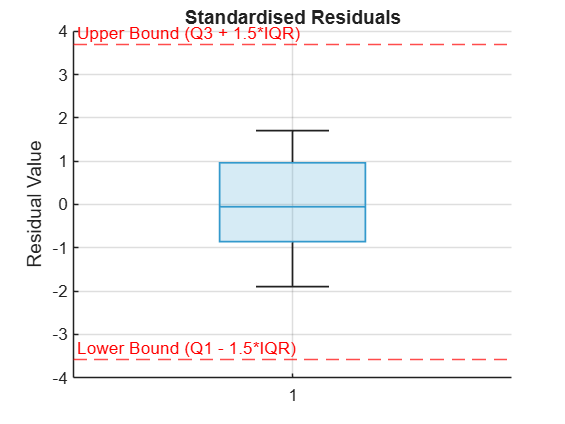


n         = residualStats.Count;      % Total number of samples
MeanVal   = residualStats.Mean;       % Sample mean
StdVal    = residualStats.Std;        % Sample std (n-1 denominator)
MinVal    = residualStats.Min;  
MaxVal    = residualStats.Max;
RangeVal  = range(standardised_res); % Max - Min

IQR = residualStats.Q3 - residualStats.Q1;   % Interquartile range

lower_bound = residualStats.Q1 - 1.5 * IQR;
upper_bound = residualStats.Q3 + 1.5 * IQR;


% --- Create the boxplot ---
figure;
boxchart(standardised_res, 'BoxFaceColor', [0.2 0.6 0.8]); % use boxplot(residuals) if preferred
hold on;

% --- Highlight IQR bounds on the plot ---
yline(lower_bound, '--r', 'Lower Bound (Q1 - 1.5*IQR)', 'LabelHorizontalAlignment','left');
yline(upper_bound, '--r', 'Upper Bound (Q3 + 1.5*IQR)', 'LabelHorizontalAlignment','left');

% --- Enhance visual appearance ---
title('Standardised Residuals');
ylabel('Residual Value');
grid on;
hold off;

**Sturges number of bins**

% ---  Sturges' formula and frequency table with histogram ---

% --- Calculate Sturges' number of bins ---
k = round(1 + 3.322 * log10(n));
classRange = (MaxVal - MinVal) / k; %could also be: classRange = range(standardised_res) / k;

fprintf('\nChi-Square Test Setup:\n');


Chi-Square Test Setup:


fprintf('\nNumber of classes = %d, Class range = %.2f\n', k, classRange);


Number of classes = 6, Class range = 0.60


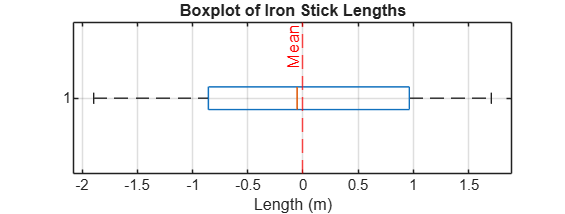


% Observed histogram and obtain their edges
% histcounts() counts how many data points fall into each bin
[histCounts, binEdges] = histcounts(standardised_res, k);

% --- Compute bin midpoints 
binCenters = binEdges(1:end-1) + classRange/2;  % Bin midpoints


%Visualisations
figure('Color','w','Position',[100 100 950 360]);
% --- Boxplot (detect outliers, spread, symmetry)
boxplot(standardised_res, 'orientation', 'horizontal');
hold on;
xline(MeanVal,'r--','Mean','LabelHorizontalAlignment','left');
xline(lower_bound,'k:','Lower Bound');
xline(upper_bound,'k:','Upper Bound');
title('Boxplot of Iron Stick Lengths');
xlabel('Length (m)');
grid on; hold off;

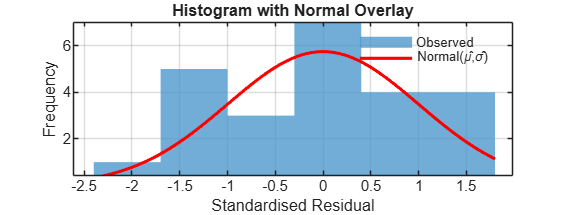


% --- Histogram with Normal PDF overlay
hObs = histogram(standardised_res, 'BinEdges', binEdges, ...
    'FaceColor', [0.3 0.6 0.8], 'FaceAlpha', 0.8, 'EdgeColor', 'none');
hold on;

% Normal PDF overlay (scaled to frequency scale: n * bin width)
x = linspace(binEdges(1), binEdges(end), 400);
y = normpdf(x, MeanVal, StdVal) * n * classRange;
hPdf = plot(x, y, 'r-', 'LineWidth', 1.8);

title('Histogram with Normal Overlay');
xlabel('Standardised Residual'); ylabel('Frequency');

% Legend at top-right
legend([hObs, hPdf], {'Observed', 'Normal(\mû,\sigmâ)'}, ...
       'Location', 'northeast', 'Box', 'off');
grid on; hold off;

% --- Compute observed and expected frequencies (Chi-square components) ---
% normcdf() gives cumulative probability of the Normal distribution
cdf_edges = normcdf(binEdges, MeanVal, StdVal);

% diff() computes differences between consecutive CDF values
bin_prob = diff(cdf_edges);

% Expected count = n × Pᵢ
expected = n * bin_prob;

% Tables for inspection
LengthBins = binCenters(:);
Observed   = histCounts(:); %Frequency
Expected   = expected(:);

% --- Table for inspection ---
Classes_number = (1:k)';  % 0-based class numbering
Table_Observed = table(Classes_number, LengthBins, Observed, Expected, ...
    'VariableNames', {'Class', 'Standard_Residuals','Observed','Expected'});
disp(Table_Observed);

    Class    Standard_Residuals    Observed    Expected
    _____    __________________    ________    ________

      1             -2.0998           1        0.87283 
      2             -1.3998           5         2.7382 
      3            -0.69984           3         5.3624 
      4          0.00016036           7           6.56 
      5             0.70016           4         5.0139 
      6              1.4002           4         2.3937 




% Quick sanity check
fprintf('Sum Observed = %.0f, Sum Expected = %.0f (should both be ~ n=%d)\n', ...
        sum(histCounts), sum(expected), n);

Sum Observed = 24, Sum Expected = 23 (should both be ~ n=24)


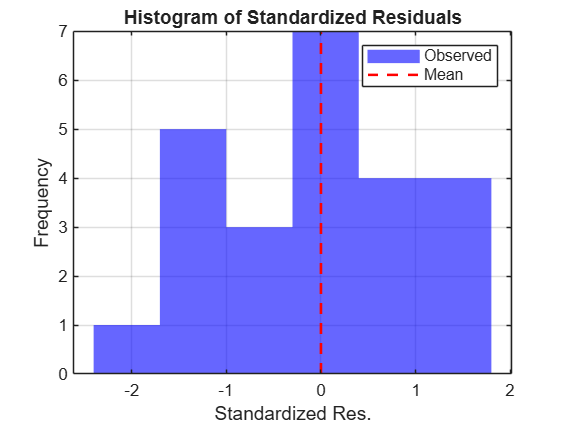


% --- Plot histogram of observed frequencies ---
figure;
histogram(standardised_res, k, 'FaceColor', [0 0 1], 'EdgeColor', 'none');
hold on;

% --- Add vertical line for mean ---
yl = ylim;
plot([MeanVal MeanVal], yl, 'r--', 'LineWidth', 1.5);

% --- Enhance the appearance ---
title('Histogram of Standardized Residuals');
xlabel('Standardized Res.');
ylabel('Frequency');
legend({'Observed','Mean'}, 'Location', 'northeast');
grid on;
hold off;

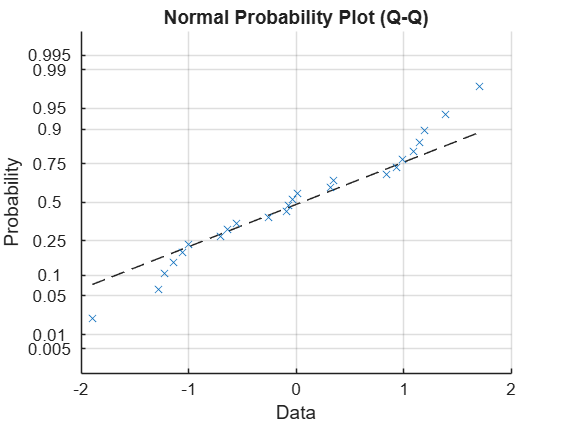


% Normal Probability Plot (Q-Q plot)
figure('Color','w');
probplot('normal', standardised_res);
title('Normal Probability Plot (Q-Q)');
grid on;


% Theory:
% If residuals are normal → Q-Q points lie near diagonal line.

**Calculate the histogram expected frequencies and verify with Chi-square**

%% --- Chi-square style residual analysis ---
% Chi-square contribution per bin
chiSqValues = ((Observed - Expected).^2) ./ Expected;
chiSqTotal  = sum(chiSqValues);  % χ² statistic
df = k - 1 - 2;                % Subtract 2 estimated parameters (μ, σ)
pValue = 1 - chi2cdf(chiSqTotal, df);  % Right-tail p-value using chi2cdf()

Chi2Table = table(LengthBins, Observed, bin_prob', Expected, chiSqValues, ...
    'VariableNames', {'CDF','Observed','BinProb','Expected',' χ²'});
% Display final table
disp(Chi2Table);

       CDF        Observed    BinProb     Expected       χ²   
    __________    ________    ________    ________    ________

       -2.0998       1        0.036368    0.87283     0.018528
       -1.3998       5         0.11409     2.7382       1.8684
      -0.69984       3         0.22343     5.3624       1.0408
    0.00016036       7         0.27333       6.56     0.029513
       0.70016       4         0.20891     5.0139      0.20503
        1.4002       4        0.099736     2.3937        1.078



fprintf('                    %-6s %11.4f %11.4f %11.4f\n', ...
    'Sum =', sum(bin_prob), sum(Expected), chiSqTotal);

                    Sum =       0.9559     22.9409      4.2402



% --- Print summary ---
fprintf('Summary:');

Summary:

fprintf('Number of observations (n): %d\n', n);

Number of observations (n): 24


fprintf('Sturges bins (k): %d\n', k);

Sturges bins (k): 6


fprintf('Class range: %.4f\n', classRange);

Class range: 0.6003


fprintf('Mean of standardized residuals: %.4f\n', MeanVal);

Mean of standardized residuals: 0.0000


fprintf('Standard deviation: %.4f\n', StdVal);

Standard deviation: 1.0000



fprintf('\nGoodness-of-fit test (Normality via Chi-square):\n');


Goodness-of-fit test (Normality via Chi-square):


fprintf('   Chi-square statistic: %.4f\n', chiSqTotal);

   Chi-square statistic: 4.2402


fprintf('   Degrees of freedom : %d\n', df);

   Degrees of freedom : 3


fprintf('   p-value            : %.6f\n', pValue);

   p-value            : 0.236668


alpha = 0.05;
if pValue > alpha
    decision = "Fail to reject H₀ → Data consistent with Normality.";
else
    decision = "Reject H₀ → Data deviate from Normality.";
end
fprintf('\nDecision: %s\n', decision);


Decision: Fail to reject H₀ → Data consistent with Normality.


fprintf('\n--- Interpretation ---\n');


--- Interpretation ---


fprintf('χ²(%d) = %.3f, p = %.3f\n', df, chiSqTotal, pValue);

χ²(3) = 4.240, p = 0.237


fprintf('→ %s\n', decision);

→ Fail to reject H₀ → Data consistent with Normality.


fprintf('Conclusion: The χ² test suggests %s\n', lower(decision));

Conclusion: The χ² test suggests fail to reject h₀ → data consistent with normality.


# 4 Predictions

% --- Basic model stats ---
n       = numel(X);
x_bar   = mean(X);
s_x     = std(X);             % sample std of X (denominator n-1)


% Residual Standard Error (RSE):
% RSE = sqrt( sum(residuals.^2) / (n - 2) )
RSE = sqrt( sum(raw_resid.^2) / (n - 2) );


%% --- Prediction for new X values ---

spending_values = [2550; 3200];   % the new X values we want predictions for
alpha = 0.05;                     % significance level
conf_level = 1 - alpha;           % e.g. 0.95
df_t = n - 2;                     % degrees of freedom for regression

% Two-sided t critical value for alpha/2 in each tail
% tinv gives the quantile such that P(T <= t) = p for T~t(df)
t_value = tinv(1 - alpha/2, df_t);

% Preallocate result arrays
SE_pred_arr      = zeros(size(spending_values));
point_pred_arr   = zeros(size(spending_values));
err_arr          = zeros(size(spending_values));
lower_arr        = zeros(size(spending_values));
upper_arr        = zeros(size(spending_values));

for i = 1:numel(spending_values)

    x_new = spending_values(i);

    % Standard Error of Prediction (your formula)
    SE_pred = RSE * sqrt( 1 + (1/n) + ((x_new - x_bar).^2) / ( (s_x.^2) * (n - 1) ) );

    % Point prediction y_hat = a + b * x_new
    y_hat = predict(mdl, spending_values(i));
    

    % Prediction interval half-width
    % error term = t_value * SE_pred
    pred_error = t_value * SE_pred;

    lower_bound = y_hat - pred_error;
    upper_bound = y_hat + pred_error;

    % Store
    SE_pred_arr(i)    = SE_pred;
    point_pred_arr(i) = y_hat;
    err_arr(i)        = pred_error;
    lower_arr(i)      = lower_bound;
    upper_arr(i)      = upper_bound;
end

%% --- Build output table ---

prediction_tbl = table( ...
    spending_values, ...
    repmat(t_value, numel(spending_values), 1), ...
    SE_pred_arr, ...
    err_arr, ...
    lower_arr, ...
    point_pred_arr, ...
    upper_arr, ...
    'VariableNames', { ...
        'Spending_x', ...
        't_value', ...
        'St_Error_of_Prediction', ...
        'Error', ...
        'Lower_Bound', ...
        'Point_Prediction', ...
        'Upper_Bound' ...
    } ...
);

disp('Prediction Results (95% interval):');

Prediction Results (95% interval):


disp(prediction_tbl);

    Spending_x    t_value    St_Error_of_Prediction    Error     Lower_Bound    Point_Prediction    Upper_Bound
    __________    _______    ______________________    ______    ___________    ________________    ___________

       2550       2.0739             822.92            1706.6      8506.8            10213             11920   
       3200       2.0739             878.29            1821.5       11802            13624             15445   




%% --- Print summary parameters table-style ---
fprintf('\nParameters:\n');


Parameters:


fprintf('   Significance level (alpha): %.2f\n', alpha);

   Significance level (alpha): 0.05


fprintf('   Prediction level (1-alpha): %.2f\n', conf_level);

   Prediction level (1-alpha): 0.95


fprintf('   x_bar (mean X): %.4f\n', x_bar);

   x_bar (mean X): 2452.3646


fprintf('   s_x  (std X)  : %.4f\n', s_x);

   s_x  (std X)  : 405.5485


fprintf('   t_value       : %.4f (df = %d)\n', t_value, df_t);

   t_value       : 2.0739 (df = 22)


fprintf('   RSE           : %.4f\n', RSE);

   RSE           : 805.3217


fprintf('   R^2           : %.4f\n', R2);

   R^2           : 0.8795


fprintf('   RMSE          : %.4f\n', RMSE);

   RMSE          : 805.3217


**Visualisations**

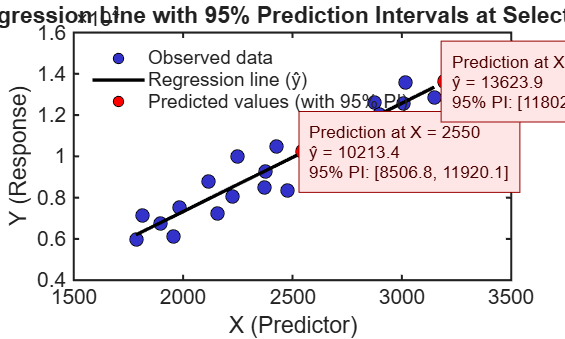

%% Smooth regression line for plotting
X_line = linspace(min(X), max(X), 200)';
Y_line = predict(mdl, X_line);

%% Plot
figure('Color','w','Position',[200 200 900 540]); hold on;

% --- 1. Observed data (blue points)
h_data = scatter(X, Y, 60, 'filled', ...
    'MarkerFaceColor',[0.2 0.2 0.8], ...
    'MarkerEdgeColor','k');

% --- 2. Regression line
h_line = plot(X_line, Y_line, 'k-', 'LineWidth', 2.0);

% --- 3. Prediction intervals (two points)
h_pred = gobjects(numel(spending_values),1); % to store handles for legend

for i = 1:numel(spending_values)
    x0  = spending_values(i);
    y0  = point_pred_arr(i);
    ylo = lower_arr(i);
    yhi = upper_arr(i);

    % interval line + caps (excluded from legend)
    plot([x0 x0], [ylo yhi], 'r-', 'LineWidth', 2, 'HandleVisibility','off');
    cap_width = range(X) * 0.01;
    plot([x0-cap_width x0+cap_width], [ylo ylo], 'r-', 'LineWidth', 2, 'HandleVisibility','off');
    plot([x0-cap_width x0+cap_width], [yhi yhi], 'r-', 'LineWidth', 2, 'HandleVisibility','off');

    % prediction marker (red dot) — include one handle per point for legend
    h_pred(i) = scatter(x0, y0, 80, 'r', 'filled', 'MarkerEdgeColor','k');

    % annotation text box
    txt = sprintf('Prediction at X = %.0f\nŷ = %.1f\n95%% PI: [%.1f, %.1f]', ...
        x0, y0, ylo, yhi);
    text(x0 + 0.02*range(X), y0, txt, ...
        'FontSize',10, 'BackgroundColor',[1 0.9 0.9], ...
        'EdgeColor',[0.6 0 0], 'Color',[0.3 0 0], 'Margin',6);
end

% --- Axis labels and title
xlabel('X (Predictor)','FontSize',12);
ylabel('Y (Response)','FontSize',12);
title('Regression Line with 95% Prediction Intervals at Selected X','FontSize',13);

% --- Clean legend: only 3 entries (blue data, black line, red predictions)
legend([h_data, h_line, h_pred(1)], ...
    {'Observed data','Regression line (ŷ)','Predicted values (with 95% PI)'}, ...
    'Location','northwest','Box','off','FontSize',11);

set(gca,'LineWidth',1.2,'FontSize',12,'Box','on');
hold off;

### Helper Function

function stats = descriptiveStats(data)
% DESCRIPTIVESTATS Compute descriptive statistics for numeric data.
% 
%   stats = descriptiveStats(data)
% 
%   Input:
%       data - Numeric vector or matrix. NaN values are ignored.
%
%   Output (structure):
%       stats.Count   - Number of non-NaN elements
%       stats.Mean    - Mean of data
%       stats.Std     - Standard deviation
%       stats.VarVal  - Sample variance
%       stats.KurtVal - Excess kurtosis (like Excel)
%       stats.SkewVal - Measure of asymmetry   
%       stats.Min     - Minimum value
%       stats.Q25     - 25th percentile (Q1)
%       stats.Q50     - Median (50th percentile)
%       stats.Q75     - 75th percentile (Q3)
%       stats.Max     - Maximum value

    % Validate input
    if ~isnumeric(data)
        error('Input must be numeric.');
    end

    % Handle NaN values and ensure column vector processing
    data = data(:);
    data = data(~isnan(data));

    % Compute statistics
    stats.Count     = numel(data);
    stats.Mean      = mean(data, 'omitnan');
    stats.Std       = std(data, 'omitnan');
    stats.VarVal    = var(data, 0);         % Sample variance
    stats.KurtVal   = kurtosis(data) - 3;   % Excess kurtosis (like Excel)
    stats.SkewVal   = skewness(data);       % Measure of asymmetry
    stats.Min       = min(data, [], 'omitnan');
    stats.Q1        = prctile(data, 25);
    stats.Q2        = prctile(data, 50);
    stats.Q3        = prctile(data, 75);
    stats.Max       = max(data, [], 'omitnan');

end